# Práctica 02 - Procesos de separación: Columna De Destilación

#### Autor: Reyes Iglesias Bruno Fernando

**Instrucción:*** Los estudiantes analizarán los procesos presentados, usarán Matlab y Python para su desarrollo. Se enfocarán en comprender los procesos, el flujo de programación y visualización de resultados.*

**1.** Mediante el método de McCabe-Thiele desarrollar el siguiente problema:

Se alimenta una columna con un flujo de 100 kmol/h que contiene un 55% del clave ligero, que entra a q=0.4. Si para conseguir una composición por la zona de rectificación del 90% en clave ligero y en agotamiento un 90% en clave pesado, se trabaja con una relación de reflujo que es 1.1 veces superior a la mínima. Siendo la volatilidad relativa 2.45, calcular:

**a.** Relación de reflujo mínimo

**b.** Reflujo real al que se trabaja

**c.** Número de etapas teóricas

**SOLUCIÓN:**

**NOTA:** Información extraída de [*Módulos de simulación con Matlab*](https://ingenieriaquimica.tech/ebooks/) (Moncada L., 2020)

    En general una columna de destilación consta de N etapas teóricas, un condensador total para el reflujo, un reboiler parcial para producir vapores y una etapa de alimentación. Estos elementos conforman la configuración para un equipo de destilación binaria a excepción de los casos donde se encuentra un azeótropo.

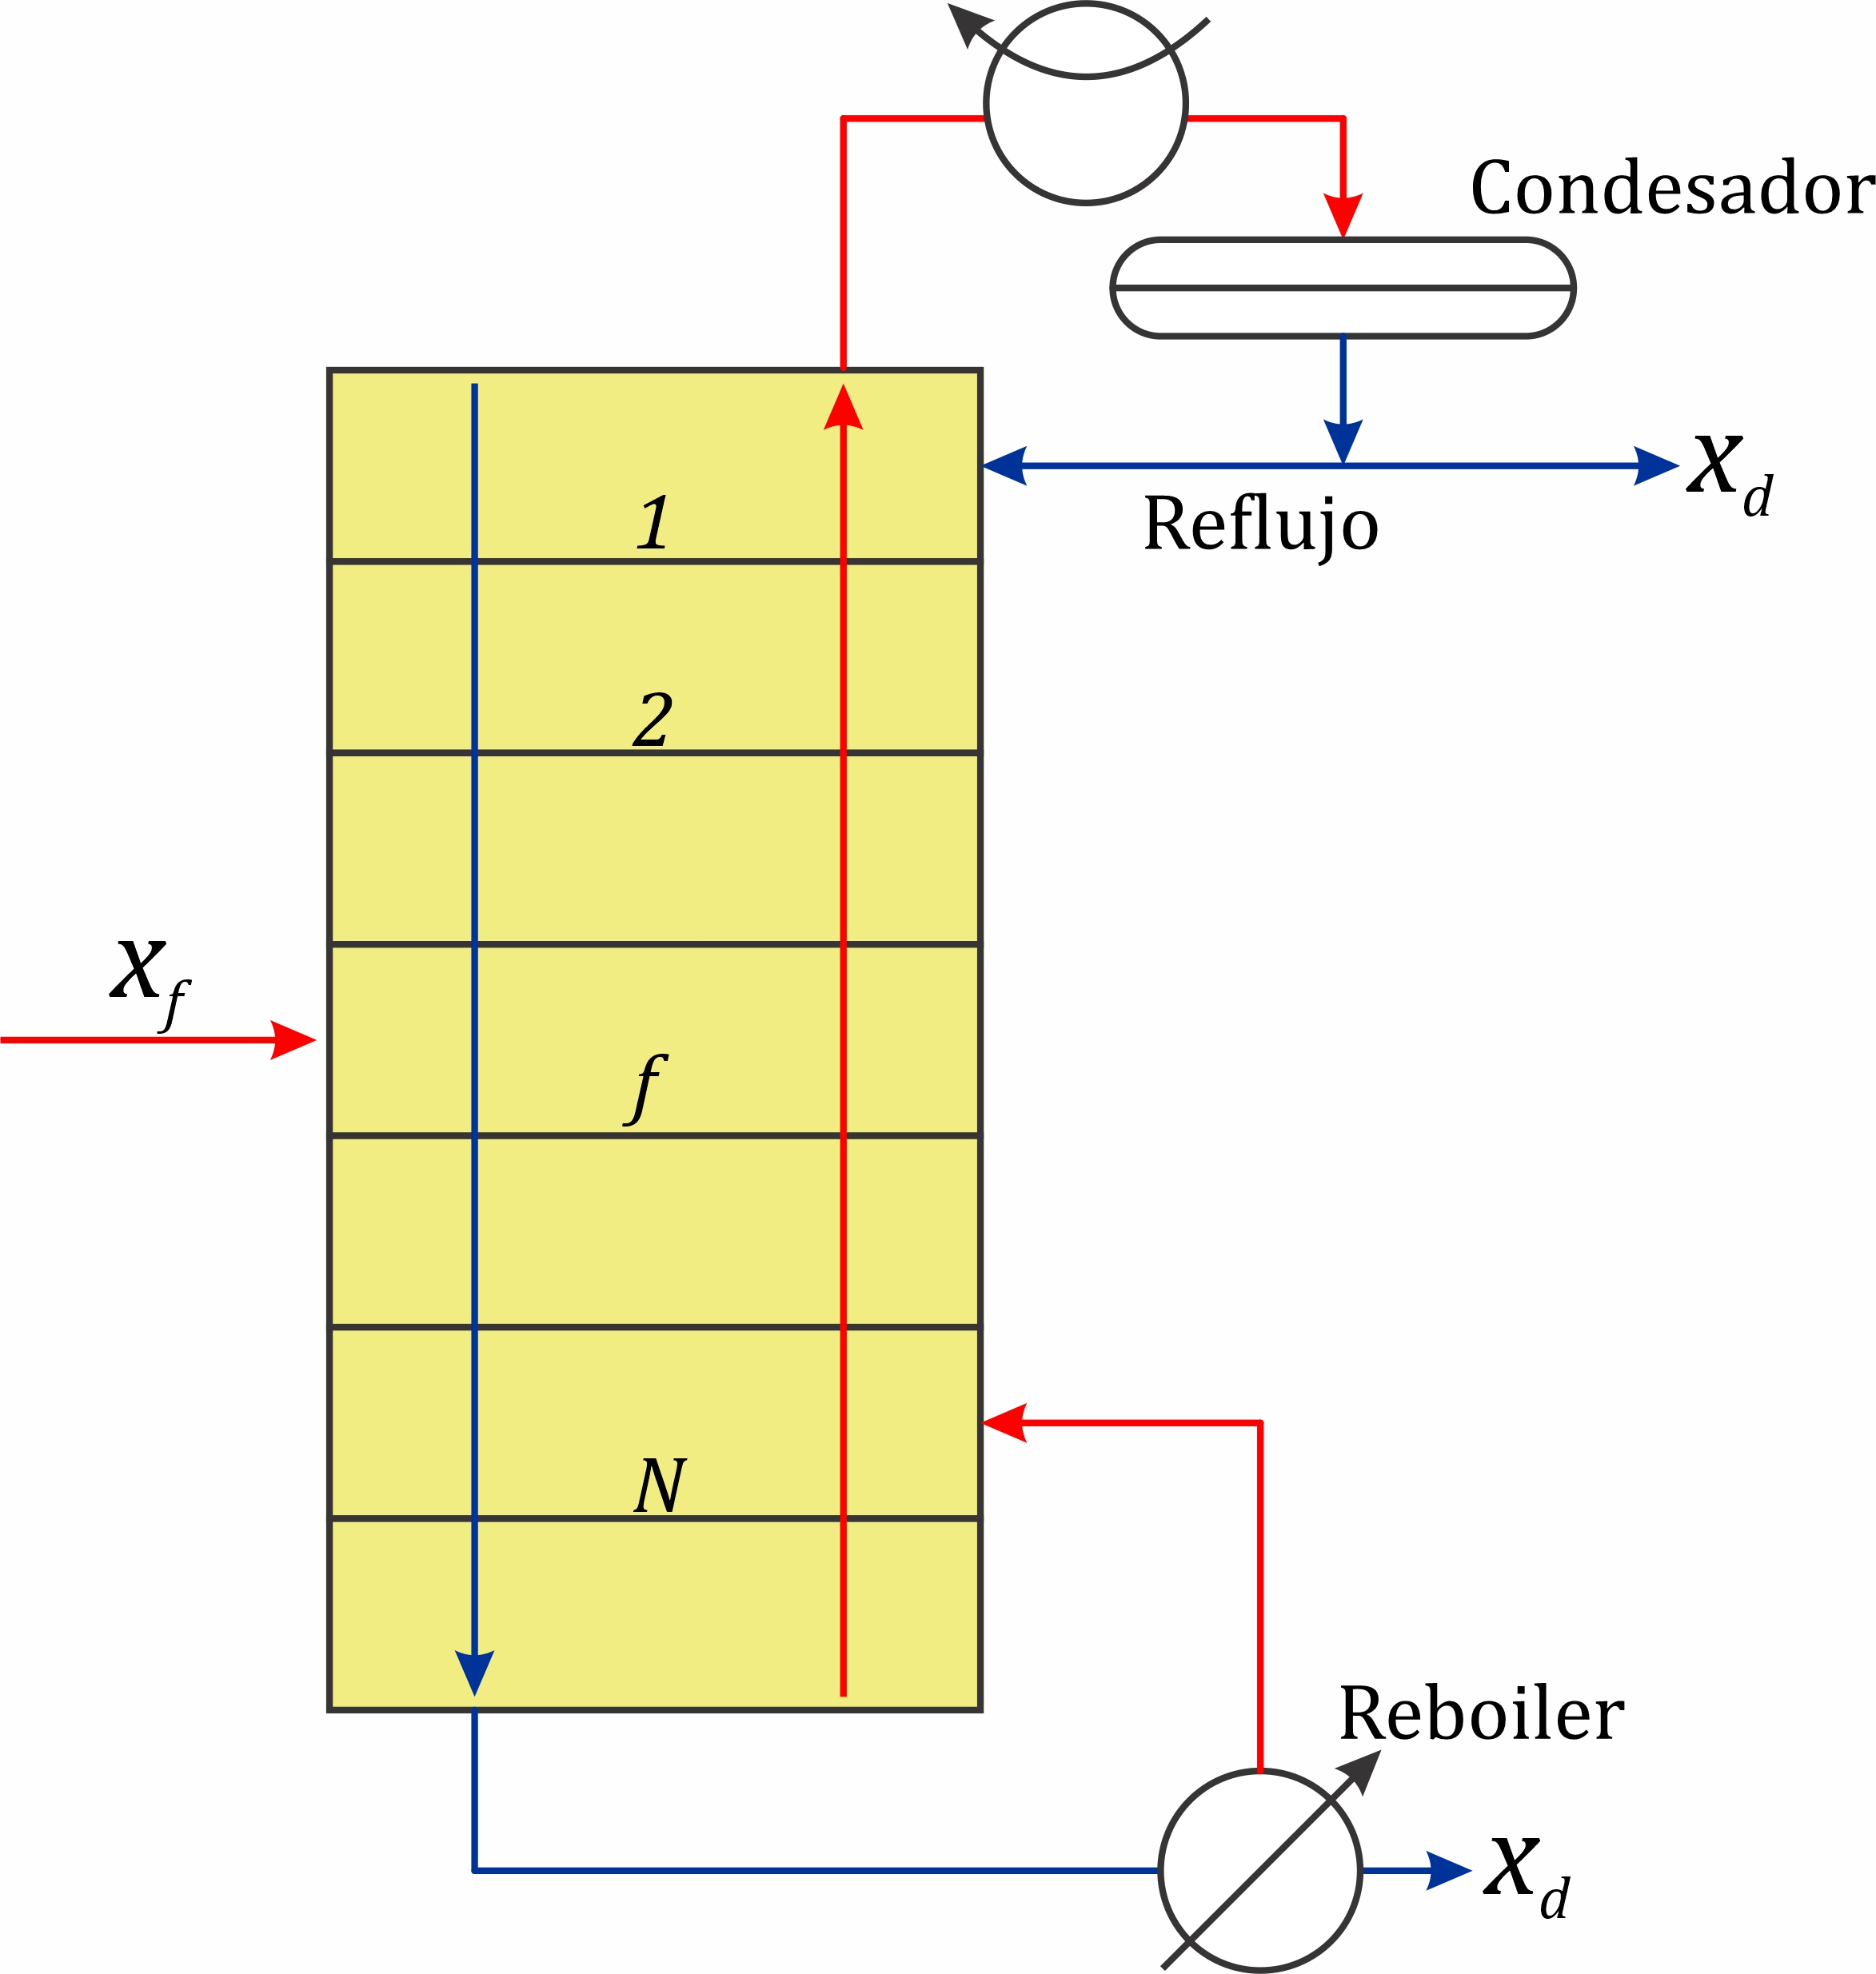

*Figura 1. Configuración básica de una columna de destilación*

**Desarrollo del Modelo:**

Se realiza un balance de materia alrededor de toda la columna, $\textrm{Acumulación}=\textrm{Entradas}-\textrm{Salidas}$. En el estado estacionario obtenemos:


$$F=D+B$$


- $F$: Flujo molar de alimentación

- $D$: Flujo molar del destilado

- $B$: Flujo molar del fondo

Ahora realizamos el balance con respecto a un componente:


$$F\cdot x_f =D\cdot x_D +B\cdot x_B$$


- $x_f$: Fracción mol del componente ligero en la alimentación

- $x_D ,x_B$: Composiciones de los productos (destilado y fondos)

Consideramos la volatilidad relativa constante en función de la temperatura, entonces se puede expresar, la relación Equilibrio Líquido-Vapor (ELV) para una mezcla binaria como:


$$y=\frac{\alpha x}{1+\left(\alpha -1\right)x}$$


- $x$: Componente ligero

- $1-x$: Componente pesado

La diferencia $y-x$ determina la cantidad de separación que se puede lograr en un escenario. Las grandes volatilidades relativas implican grandes diferencias en los puntos de ebullición y una fácil separación. Los puntos de ebullición cercanos implican una volatilidad relativa más cercana a la unidad, como se muestra a continuación cuantitativamente

Ahora realizamos un balance de materia del componente i para una etapa n:


$$\frac{{\textrm{dN}}_{i,m} }{\;\textrm{dt}}=\left(L_{n+1} x_{i,n+1} -V_n y_{i,n} \right)-\left(L_n x_{i,n} -V_{n-1} y_{i,n-1} \right)$$


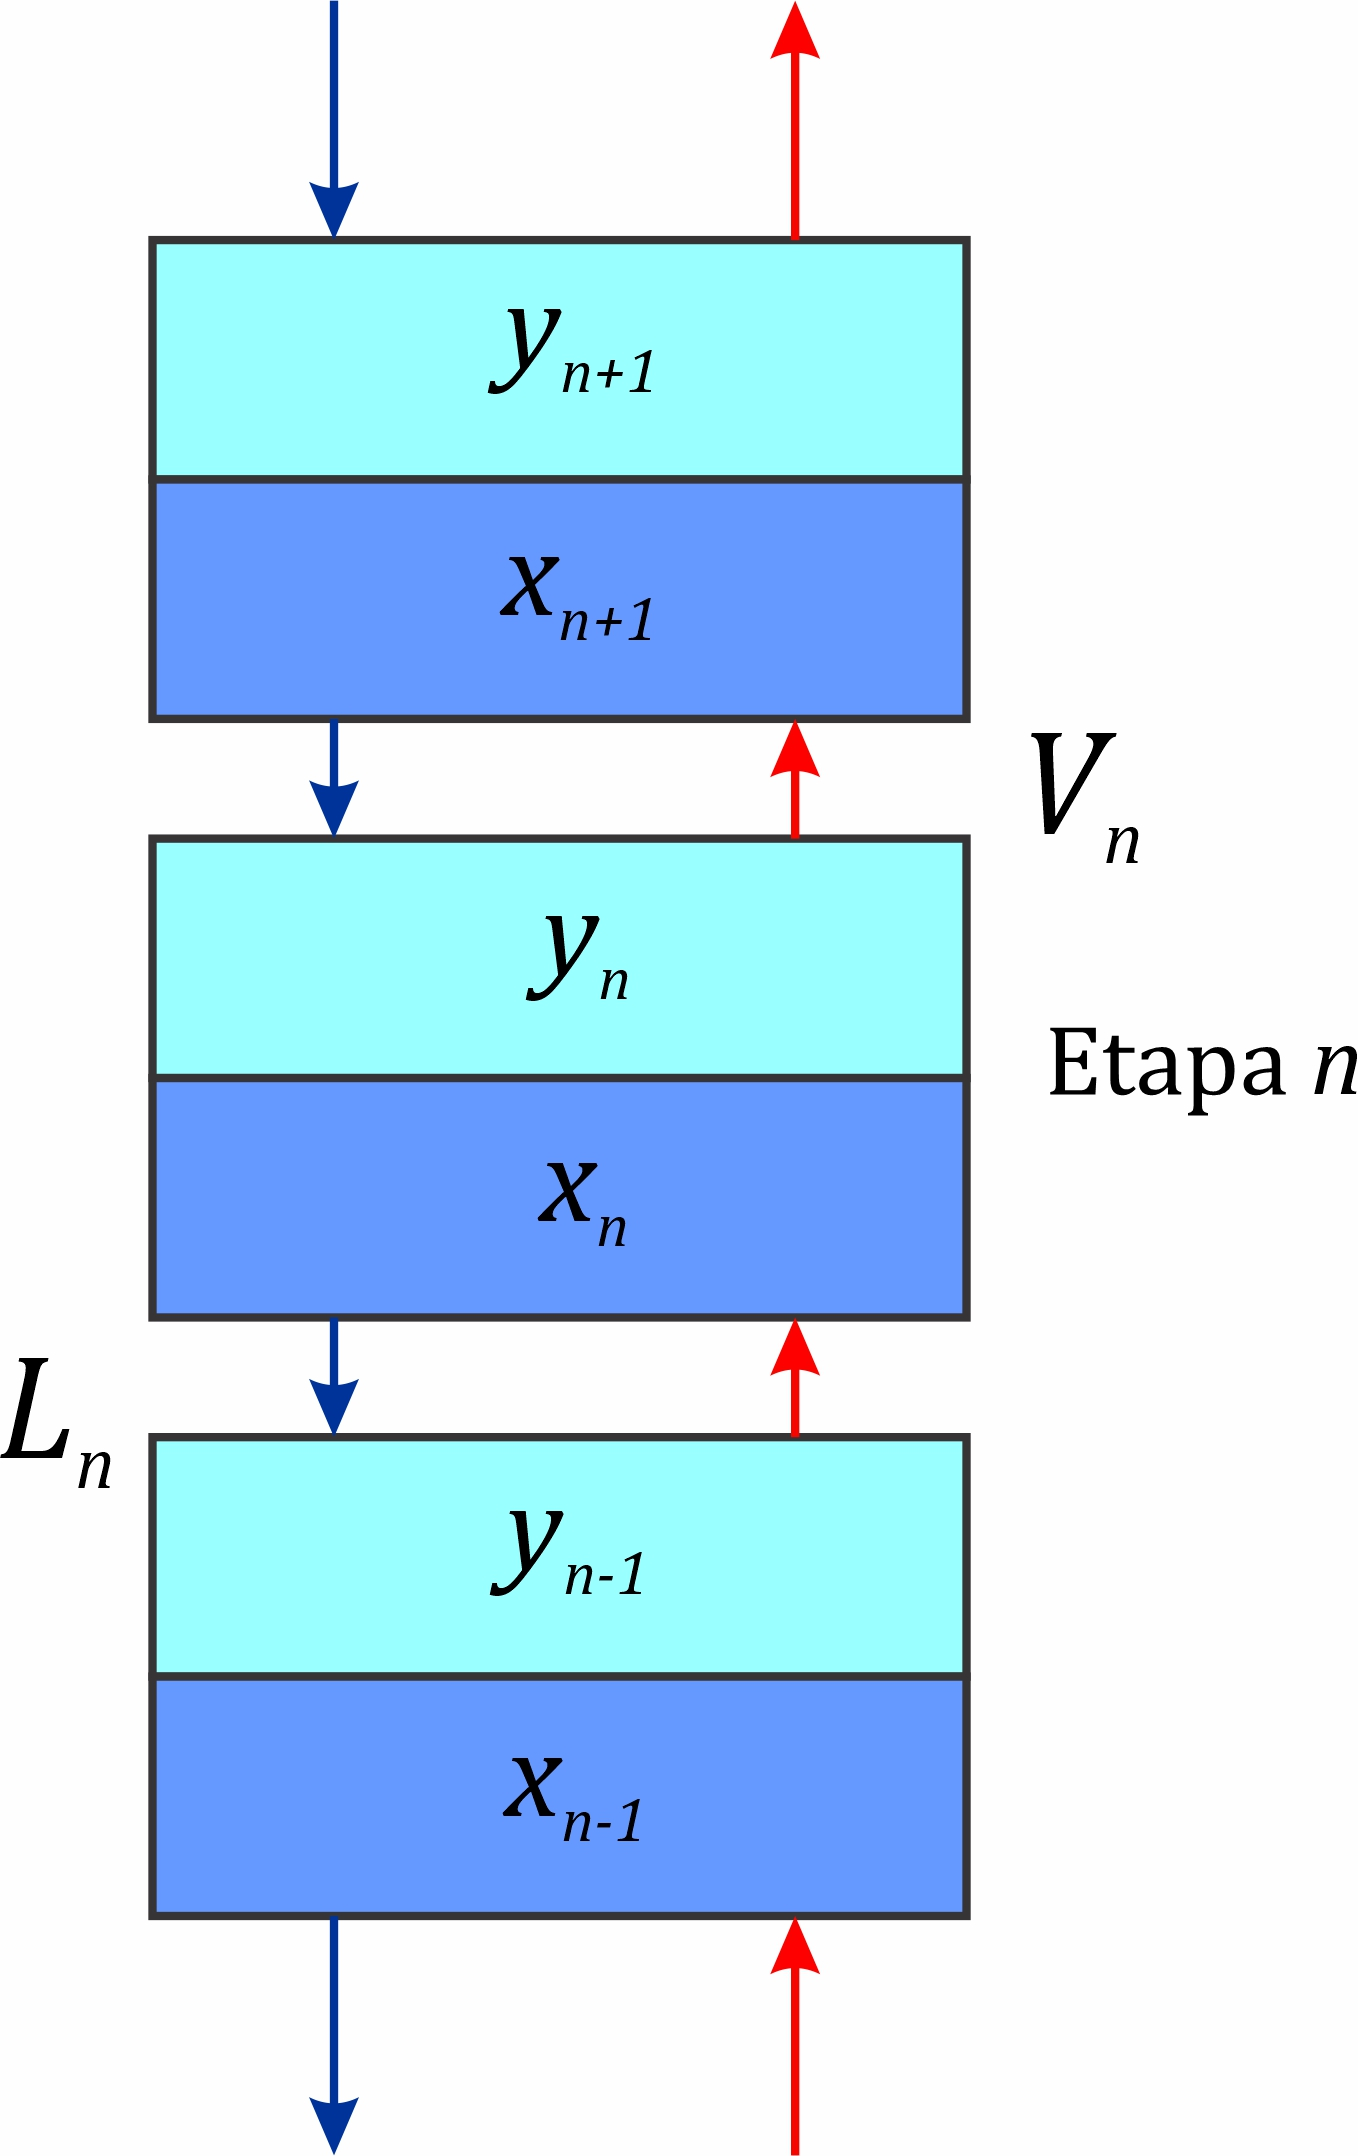

*Figura 2. Diagrama del balance para una etapa n*

- $N_{i,n}$: Número de moles del componente i en la etapa n

- $L_n$: Flujo molar líquido que sale de la etapa n

- $V_n$: Flujo molar vapor que sale de la etapa n

Al estado estacionario la diferencial se iguala a cero.

Es conveniente definir el flujo de material neto que sube desde la etapa n hacia n+1


$$w_{i,n} =V_n y_{i,n} -L_{n+1} x_{i,n+1}$$


En el estado estacionario el flujo neto es el mismo en todas las etapas: $w_{i,n} =w_{i,n+1} =w_i$

Reescribimos:


$$y_{i,n} =\frac{L_{n+1} }{V_n }x_{i,n+1} +\frac{1}{V_n }w_{i,n}$$


Consideramos el flujo molar tanto vapor como líquido constante, entonces:


$$L_n \approx L_1 =L$$



$$V_n \approx V_1 =V$$


En la sección superior, el transporte neto del componente de ligero es $w=x_D D$. Insertado en el balance de materia en cada etapa, obtenemos la línea de operación para la sección superior:


$$y_n ={\left(\frac{L}{V}\right)}_T x_{n+1} +\frac{D}{V_T }x_D$$


En la sección inferior $x_B B$, con lo que obtenemos:


$$y_n ={\left(\frac{L}{V}\right)}_B x_{n+1} +\frac{D}{V_B }x_B$$


**Alimentación fracción líquida (línea q)**

Describe el cambio en caudales de líquido y vapor en la etapa de alimentación:


$$\Delta L_F =\textrm{qF}$$



$$\Delta V_F =\left(1-q\right)F$$


Cuando asumimos flujos molares constantes en cada sección, obtenemos la siguiente relación para los flujos:


$$D=V_T -L_T$$



$$B=L_B -V_B$$



$$V_T =V_B +\left(1-q\right)F$$



$$L_B =L_T +\textrm{qF}$$


Ecuación de la línea q:


$$y=\frac{q}{q-1}x-\frac{x_f }{q-1}$$


%% Practica 02 - Columna de destilacion
% Autor: Reyes Iglesias Bruno Fernando
%% Metodo de McCabe-Thiele
F = 100; % Flujo molar total de la alimentacion
xf =0.55; % Fraccion molar de la alimentacion
q =0.4; % La fraccion de líquido en la alimentacion
xd =0.9; % Fraccion molar del destilado 
xb =0.1; % Fraccion molar del fondo
ratio = 1.1; % Relacion de reflujo
a = 2.45; % La volatilidad relativa

%% Balance alrededor de la columna
D = F.*(xf-xb)./(xd-xb); % Flujo molar del destilado
B = F-D; % Flujo molar del fondo
fprintf('Flujo molar del destilado: %1.6g\n',D);

Flujo molar del destilado: 56.25


fprintf('Flujo molar del fondo: %1.6g\n',B);

Flujo molar del fondo: 43.75


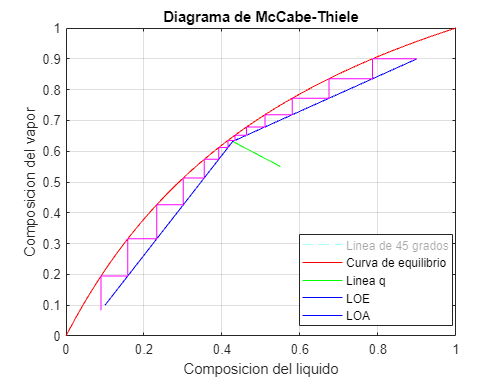

%% Grafica ELV
x = linspace(0,1); % Fraccion mol del componente ligero en la fase líquida
plot(x,x,'--c','DisplayName','Linea de 45 grados');
title('Diagrama de McCabe-Thiele')
xlabel('Composicion del liquido')
ylabel('Composicion del vapor')
grid on
hold on
y = a.*x./(1+x.*(a-1)); % Fraccion mol del componente ligero en la fase vapor
plot(x,y,'r','DisplayName','Curva de equilibrio'); % Grafica y en funcion de x en ELV
%% Ecuacion linea q (y=m*x+n)
m = q./(q-1);
n = xf-m.*xf;
Zf = -n.*(q-1);
%% Interseccion linea-q con ELV
syms x0
f = a*x0/(1+x0*(a-1))==m*x0+n;
[x0] = solve(f);
x0 = eval(x0);
x0 = x0( x0>=0 );
y0 = m*x0+n;
%% Linea Operacion Enriquecimiento (LOE)
% [y=(R/(R+1))X+Xd/(R+1)]
syms m1 n1
f1 = m1*x0+n1*xd==y0;
f2 = m1*xd+n1*xd==xd;
[m1,n1] = solve(f1,f2);
m1 = eval(m1);
n1 = eval(n1);
% m=R/(R+1)
r = m1/(1-m1); % Reflujo minimo
R = ratio*r; % Reflujo real
m2 = R/(R+1);
n2 = xd-m2*xd;
%% interseccion linea q y LOE 
syms xz yz
a1 = m*xz+n==yz;
a2 = m2*xz+n2==yz;
[xz, yz]=solve(a1,a2);
xz = eval(xz);
%% Graficamos linea q
x2 = linspace(xz,xf);
y2 = x2.*m+n;
plot(x2,y2,'g','DisplayName','Linea q');
%% Grafica LOE
x3 = linspace(xz,xd);
y3 = m2.*x3+n2;
plot(x3,y3,'b','DisplayName','LOE');
%% Linea Operacion Agotamiento (LOA) 
syms m3 n3
f3 = m3*xb+n3==xb;
f4 = m3*xz+n3==yz;
[m3,n3] = solve(f3,f4);
m3 = eval(m3);
n3 = eval(n3);
% Grafica LOA
x4 = linspace(xb,xz);
y4 = m3.*x4+n3;
plot(x4,y4,'b','DisplayName','LOA');
legend("Position", [0.60952,0.14883,0.275,0.21892])
legend AutoUpdate off
t = xd; t1 = xd; p = xd;
%% Graficamos etapas
i = 0;
syms x y
while t>xb
    h = solve(y==a*x/(1+x*(a-1)), y==t1+0*x);
    plot([h.x,t],[p,p],'m') % Horizontal
    t = h.x;
    if t>xz
        p = subs(R*x/(R+1)+xd/(R+1),h.x);
        plot([h.x,h.x],[p,h.y],'m') 
        t1 = p;
        i = i+1;
    elseif t<xz
        p = subs(x.*(yz-xb)/(xz-xb)-xb*(yz-xb)/(xz-xb)+xb,h.x);
        plot([h.x,h.x],[p,h.y],'m') 
        t1 = p;
        i = i+1;
    end
end

fprintf('El N°. de las etapas requeridas es: %d.\n',i);

El N°. de las etapas requeridas es: 13.


fprintf('El N°. de bandejas requeridas es: %d.\n',i-1);

El N°. de bandejas requeridas es: 12.
